%% Treinamento da Rede Adaline
% A rede Adaline é utilizada como aproximador de funções.
%
clc
clear
close
x = [0.2 0.3;
    0.1 0.4;
    0.4 0.3;
    0.11 0.9;
    0.84 0.6;
    0.1 0.2;
    0.6 0.2;
    0.2 0.2;
    0.7 0.8;
    0.1 0];
d = [0.13 0.17 0.25 0.822 1.065 0.05 0.4 0.08 1.13 0.01];
bias = 1;
epoca = 0;
epocamax = 10;
eps =1e-2;
w = [8.44 8.28];
a = 1;
ite = 0;
N = length(x);
pesos = [];
while (epoca < 1)
    for i=1:N
        u(i) = x(i,:)*w';
       
        % Função de ativação Linear por Partes
        % OBS.: Neste caso, pode utilizar a outra forma da função de ativação
        if(u(i) >= 0.5)
            y(i) = 1;
        end
        if ((u(i)>-0.5)||(u(i)<0.5))
            y(i) = u(i)+0.5;
        end
        if (u(i)<= -0.5)
            y(i) = 0;
        end
        
        e(i) = d(i) - y(i);
        w = w + a*e(i)*x(i,:);
        bias = bias + a*e(i);
        ite = ite + 1;
        pesos = [pesos; w];
        
        MSE = sum(e.^2)/(2*N);
        
    end
    epoca = epoca +1;
end
disp(pesos)

    7.5316    6.9174
    7.1466    5.3774
    5.2579    3.9608
    4.8375    0.5218
    1.6358   -1.7651
    1.6097   -1.8173
    1.1883   -1.9577
    1.1351   -2.0110
    1.9261   -1.1070
    1.8578   -1.1070


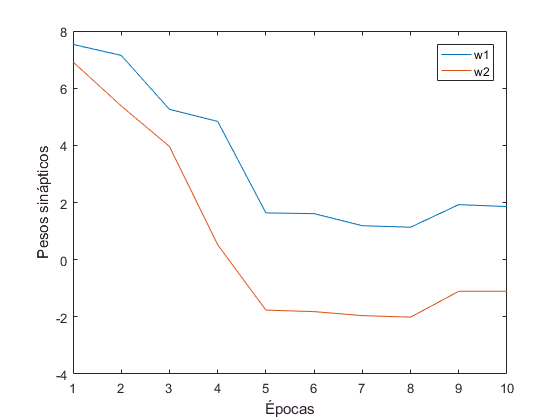

% Gráfico de convergência dos pesos sinápticos
% Veja que em apenas 10 épocas não é possível uma convergência adequada dos pesos sinápticos.
% Faça testes reduzindo a taxa de aprendizagem e aumentando o número de épocas de treinamento.

w1 = pesos(:,1);
w2 = pesos(:,2);
title('Convergência dos pesos')
epocas = 1:length(w1);
plot(epocas,w1);
hold on
plot(epocas,w2);
xlabel('Épocas');
ylabel('Pesos sinápticos');
legend('w1','w2');